# Adaptive Intelligence COM3240

# Lab 6: Reinforcement Learning

## Learning Outcomes

- Understand how reinforcement learning works.

- Ability to develop a simple reinforcement learning scenario.

# Lecture Overview

## Reinforcement Learning

- Reinforcement learning is learning by maximising a reward signal (*Reinforcement Learning: An Introduction by Richard S. Sutton and Andrew G. Barto*).

- In a typical reinforcement learning scenario a learner (or agent) has to achieve a specific goal by performing correct actions. 

- The "value" of an action is estimaded by state-action pair functions which are called value funtions and mathematically are described by the notation $Q^{\pi } \left(s,a\right)$.

- Alternative, value funtions estimate how good a particular action will be on a given state, under a policy.

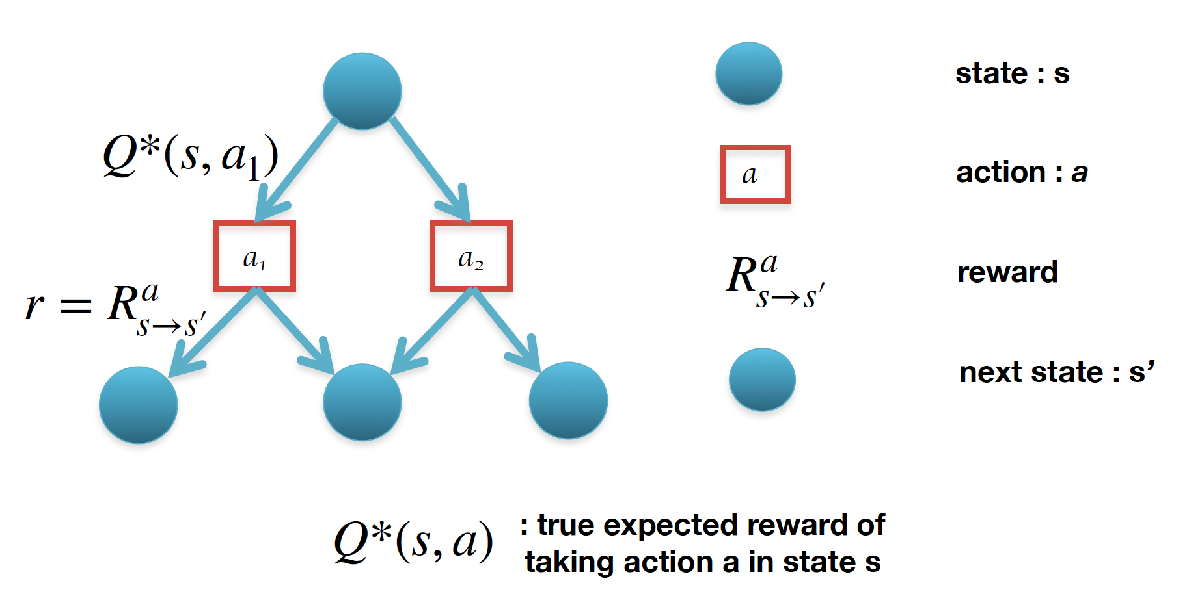

- How do we stimate $Q\left(s,a\right)$? => **We explore**. How do we choose an action? => **We choose the action that maximizes our reward**.

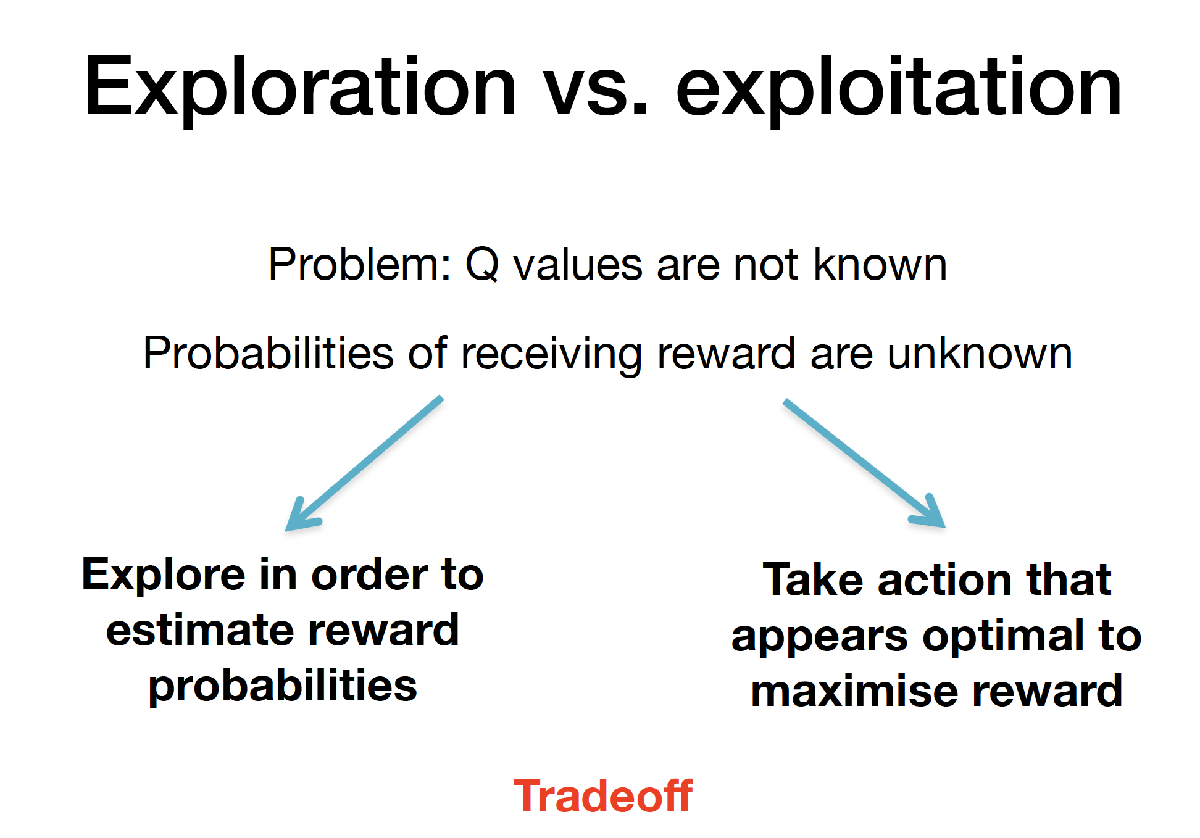

- Exporation vs. exploitation policies (e.g. ε-greedy, soft-max, optimistic greedy).

# Laboratory 6: Reinforcement Learning

## Exercise

A monkey is randomly presented with two alternative images. One shows a balloon and the other a bicycle. In front of the monkey, there are two buttons, one Green and one Red. Every time the balloon is presented and the monkey presses the Green button, it receives a bit of juice (reward). Similarly, if the bicycle is presented and the Red button is pressed, it again receives juice. No other combination is rewarded. In this simple setup, your monkey, child or artificial agent can learn a specific mapping (Balloon− >Green) and (Bicycle− >Red) from rewards.

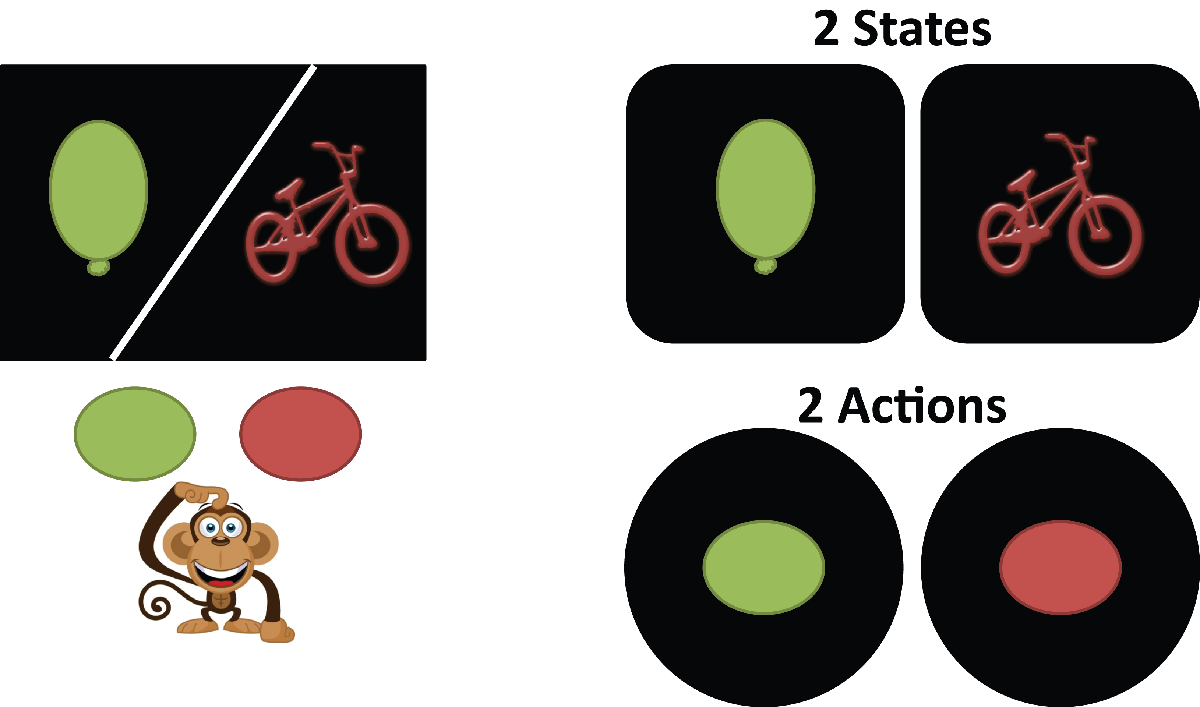

- Write code that implements this scenario. The artificial agent may found itself in two states, ”bicycle” or ”balloon”, with equal probabilities. For this reason, you need to use a random generator (rand). From each of the two states, it can choose two actions Red or Green, based on the Q values of the state-action pair. You can use the update rule for Q values we covered in the class in order to learn the optimal actions. Initialise the Qs randomly between 0 and 1 (rand). You can use a Greedy policy. Pre-define the number of consequent presentations (trials). If in difficulties with setting up variables, please ask the demonstrators for help. **Note:** In order to make the algorithm work, you need to find appropriate parameters. Try different values for the learning rate.

- Plot the average total reward as a function of the trials. This is the learning curve and successful learning means that the reward increases as the trial number increases (up to a maximum value). If in difficulties with plotting commands, please ask the demonstrators.

- In order to draw conclusions we need to repeat this procedure many times and show an average learning curve. Repeat the above procedure 10 times and plot the average graph with errorbars (Matlab commands mean and errorbar).

- The use of an epsilon-greedy policy would make any difference in this case? Modify your code accordingly and explain your results. What is the best value for epsilon in this case and for which reason?

- The rules of the game change. Initial Q values are set to zero. In case of a wrong response, a small reward of 0.1 is administered. In case of a correct response, a reward of 10 with probability 1/10 is given (i.e. in 1 out of 10 cases). Change your code accordingly. Would you be able to achieve maximum reward with the parameters you have used earlier? If not, how should you change the learning rate and the epsilon parameter?

clear all   % clear the workspace
close all   % close all the windows

## ***Parameters and variables***

% This script calls the function monkey_template function (1 run)
% The code has been developped as a demo, see if you can improve it.
% For instance there is no check whether the parameters are correct or not.

% Parameter setup
nTrials = 250; % should be integer >0
learningRate = 0.1; % should be real, Greater than 0
epsilon = 0.10; % Should be real, Greater or Equal to 0; epsion=0 Greedy, otherwise epsilon-Greedy

fontSize=18;

repetitions=1000; %should be integer, greater than 0; for statistical reasons


## ***Call main function***

% Parameters for the deterministic reward
rfail = 0;
rsuccess = 1;
p = 1.0;

% To compare the effect of epsilon, we will try multiple values of it
n_epsilons = 6;
epsilons = linspace(0.0, 1.0, n_epsilons);

totalRewards=zeros(repetitions,nTrials, n_epsilons);

% For each value of epsilon, repeat the experiment multiple times and save
% the learning curves.
for k=1:n_epsilons
    for j=1:1:repetitions
        totalRewards(j,:,k) = monkey_template(nTrials, learningRate, epsilons(k), rfail, rsuccess, p); %simulate one episode and store rewards obtained for each trial in the episode
    end
end


% Plot the average reward as a function of the number of trials --> the average has to be performed over the episodes
%plot(mean(totalRewards)',1:nTrials,'k-');
figure
hold on
for k=1:n_epsilons
    h1=errorbar(mean(totalRewards(:,:,k)), std(totalRewards(:,:,k))./sqrt(repetitions)); %errorbars are equal to standard error i.e. std/sqrt(samples)
    set(h1,'linewidth',2);
end
hold off
legend(string(epsilons));
xlabel('Trial','fontsize',fontSize);
ylabel('Average Reward','fontsize',fontSize);
title('Average reward for different epsilons');
set(gca,'fontsize',fontSize);

For the initial task, exploration is not very important as there are only a small set of states and actions. When using the e-greedy policy, the Q-values are learnt quickly and then the random actions reduce the average reward, which theoretically should be $E\left(r\right)=1-\frac{\varepsilon }{2}\;$so the optimal value is $\varepsilon =0$. This will depend on the initial Q-values and what happens for tied Q-values.

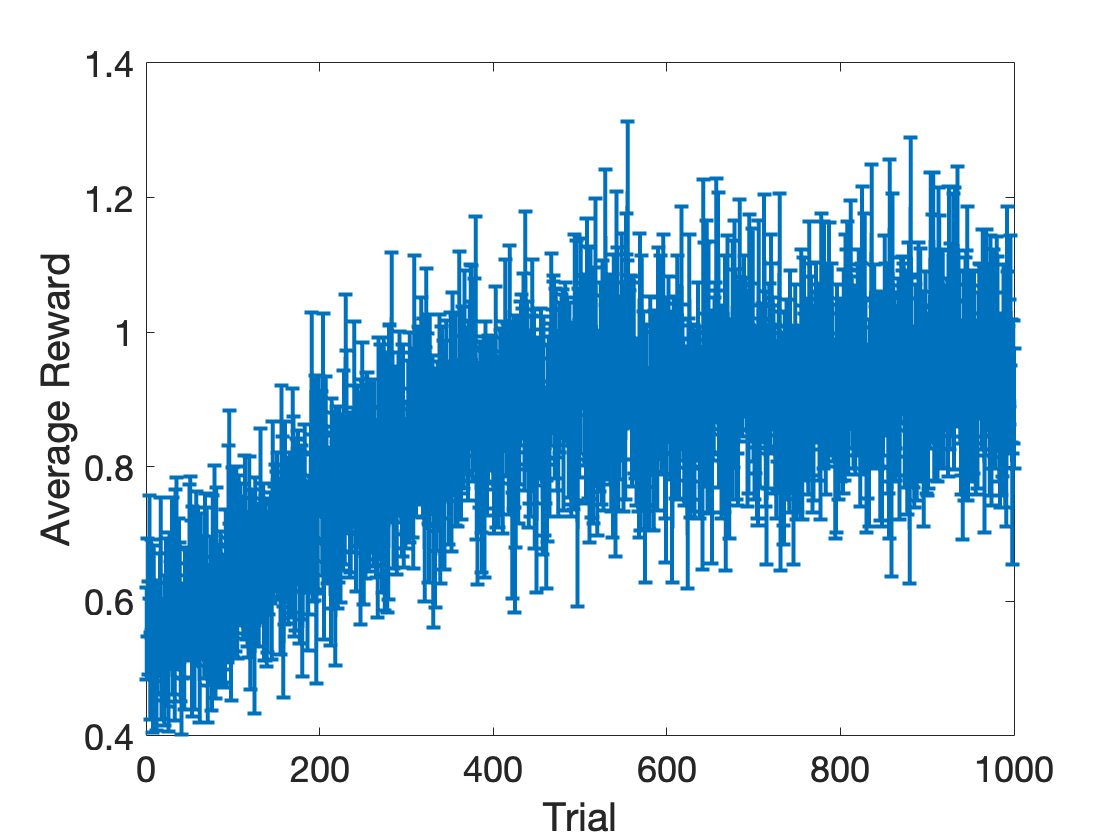

nTrials = 1000; % should be integer >0
learningRate = 0.01; % should be real, Greater than 0
epsilon = 0.10;


totalRewards2 = zeros(repetitions,nTrials);

% Set up the case with a random reward
rfail = 0.1;
rsuccess = 10;
p = 0.1;

for j=1:1:repetitions
    totalRewards2(j,:) = monkey_template(nTrials, learningRate, epsilon, rfail, rsuccess, p); %simulate one episode and store rewards obtained for each trial in the episode
end

% Plot the average reward as a function of the number of trials --> the average has to be performed over the episodes
%plot(mean(totalRewards)',1:nTrials,'k-');
figure
h1=errorbar(mean(totalRewards2), std(totalRewards2)./sqrt(repetitions)); %errorbars are equal to standard error i.e. std/sqrt(samples)
set(h1,'linewidth',2);
xlabel('Trial','fontsize',fontSize);
ylabel('Average Reward','fontsize',fontSize);
set(gca,'fontsize',fontSize);

Now the success reward is random so there is a high chance that the agent will think the wrong action is the better one to take initially. It is important to use a low learning rate and a longer number of trials to learn the Q-values properly. Exploring will be more important here to force the agent to try new actions in case it initially learns the wrong action. Now the theoretical average reward will be $E\left(r\right)=\left(1-\frac{\varepsilon }{2}\right)Q^* \left(\mathrm{correct}\right)+\frac{\varepsilon }{2}Q^* \left(\mathrm{wrong}\right)=\left(1-\frac{\varepsilon }{2}\right)+\frac{\varepsilon }{2}\frac{1}{10}\;$. The best case is still when $\varepsilon =0$ but even a large epsilon will give better performance than a Greedy policy since there is a high chance the Greedy policy will learn the incorrect action. A small or decaying $\varepsilon$will be best. 

## *Main function*

function Rewards = monkey_template(nTrials, learningRate, epsilon, rfail, rsuccess, p)

    % expected rewards: initially random
    Qvalue = rand(2, 2);
    
    % actions
    Red = 1;
    Green = 2;
    
    % inputs (states)
    Baloon = 1;
    Bicycle = 2;
    
    % output: rewards for each trial
    Rewards = zeros(1, nTrials);
    
    for trial = 1:nTrials
        % present a picture / state
        Image = (rand < 0.5) + 1; % Half times Balloon, half times Bicycle
                
        %% TODO: turn algorithm into an epsilon-Greedy one 
        %% (random actions can be selected with a probability = epsilon)    
        eGreedy = (rand<epsilon); %with probability epsilon chose action at random; if epsilon=0 then always choose Greedy
        
        if or((Qvalue(Image,Red)==Qvalue(Image,Green)),eGreedy)
            %if Qvalues are the same or epsilon>0 (e-Greedy, chose at random with probability epsilon) chose one at random
            Action=(rand<0.5)+1; 
        else
            %will result Action=2 (Green) if Qvalue(Image,Green)>Qvalue(Image,Red) and Action=1 (Red) otherwise (Greedy) 
            Action=(Qvalue(Image,Green)>Qvalue(Image,Red))+1; 
        end
        
    
        %Collect reward
        if and((Image==Baloon),(Action==Green)) || and((Image==Bicycle),(Action==Red))
            if rand < p
                r=rsuccess;
            else
                r=0;
            end
        else
            r=rfail;
        end
        
        %Update Q values
        Qvalue(Image,Action)= Qvalue(Image,Action)+learningRate*(r-Qvalue(Image,Action));
        
        
        % store reward
        Rewards(1, trial) = r;    
    end
end